# Calculate Heart Rate from Electrocardiogram Data

This example shows how to do a simple analysis of an electrocardiogram (ECG) signal. The signal is a measure of electrical activity of the heart over time.

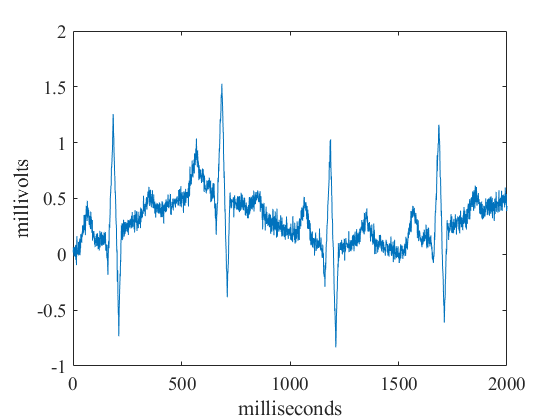

S = load('noisyecg.mat');
noisyECG = S.noisyECG_withTrend;
plot(noisyECG)
xlabel('milliseconds')
ylabel('millivolts')

## Remove Trends in the Data

The signal is measured by electrodes attached to the skin and is sensitive to disturbances such as power source interference and noises due to movement.  The above signal shows a baseline shift and therefore does not represent the true amplitude. We can use the ***Remove Trends*** Live Editor Task to fit the baseline shift to a polynomial and remove it.

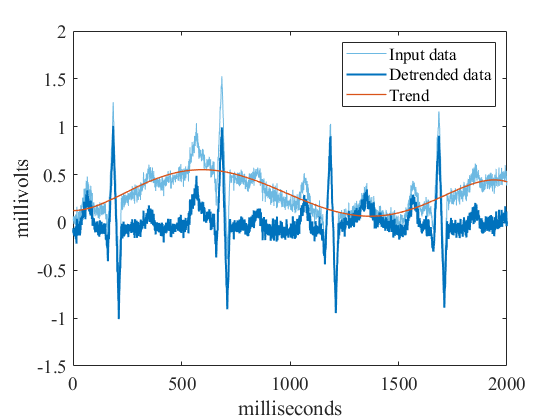

% Remove trend from data
detrendedECG = detrend(noisyECG,5);

% Visualize results
clf
plot(noisyECG,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedECG,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(noisyECG-detrendedECG,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend
xlabel('milliseconds')
ylabel('millivolts')

## Find the R Wave Maximums

In an elecrocardiogram, the R wave is the large upward deflection in the signal that represents the deploarization of the main mass of the heart's ventricles.  The R-waves can be detected by thresholding peaks above 0.5mV.  We can use the ***Find Local Extrema*** Live Editor Task.

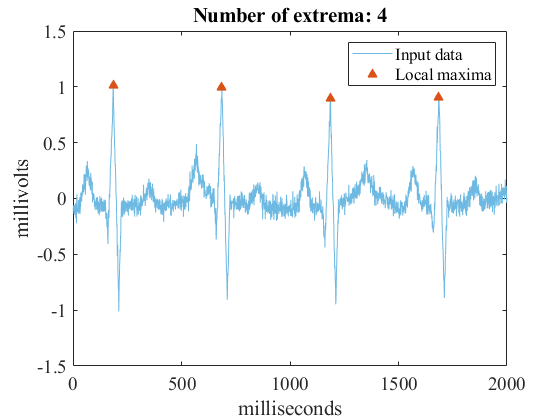

% Find local maxima
ismax = islocalmax(detrendedECG,'MinProminence',0.9);

% Visualize results
clf
plot(detrendedECG,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(ismax),detrendedECG(ismax),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(ismax))])
hold off
legend
xlabel('milliseconds')
ylabel('millivolts')

## Calculate the Heart Rate

Knowing the time, in milliseconds, between the peaks in the ECG signal, we can calculate the heart rate.

maxIndices = find(ismax);
msPerBeat = mean(diff(maxIndices));
heartRate = 60*(1000/msPerBeat)

heartRate =        119.92


Copyright (c) 2019 - 2020, The MathWorks, Inc.